# **Лабораторная работа №1**

## **Динамическая модель многозвенного манипулятора**

**Студент: Топольницкий А.**

**Группа: R4134c**

**Поток: МИУР 1.1**

**Вариант: 2 **

**Робот: ABB IRB140**

***Задание:***

*Решить задачу обратной динамики, по которой требуется вывести параметры динамической модели*

Ход работы

clear
clc

Загрузим модель робота из тулбокса по команде

mdl_irb140;

Выведем таблицу, в которой отображены геометрические параметры в представлении Денавита-Хартенберга

irb140.config;
irb140.teach();% открывает графическое окно и позволяет изменять о.к. q_i

Необходимо рассчитать инерциальные параметры звеньев, при этом хотя бы одно звено робота должно иметь квадратное сечение и одно круглое. Габариты сечения в диапазоне 20 - 80 мм. Масса каждого звена в диапазоне от 0.5 до 10 кг

Начнём с массы. Задаём массив масс и через сущность робота обращаемся к каждому звену и его параметру массы, в цикле присваиваем

m = [10 8 6 4 2 2];

for i = 1:6
    irb140.links(1,i).m = m(i);
end

Теперь зададим параметры сечения и координаты ц.м., через параметр ДХ длины а

w = [0.08 0.06 0.06 0.04 0.04 0.02];

for i = 1:6
    irb140.links(1,i).r = [irb140.links(1,i).a/2 0 0];
end

Необходимо рассчитать тензоры инерции для каждого звена. Для цилиндрического звена тензор инерции имеет следующий вид. В задании предполагаем, что ось звена сонаправлена с осью х, потому итоговый тензор будет иметь немного другой вид.

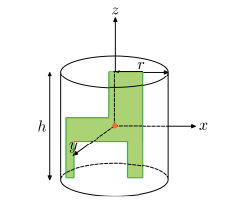

В случае, если сечение звена представляет собой параллелепипед, то тензор инерции будет иметь следующий вид

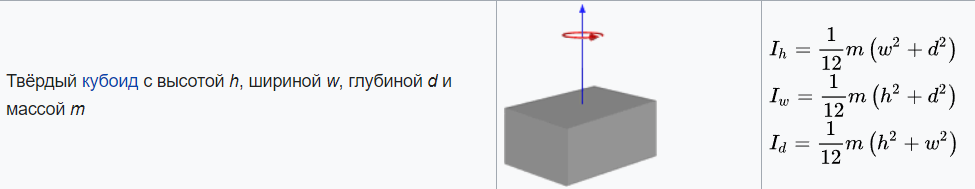

Пускай 1 звено имеет прямоугольное сечение, остальные - кругое. Тогда можно рассчитать моменты инерции

for i=1:6
    irb140.links(1,i).I = zeros(3,3);
end

for i=1:6
    if i == 1
        irb140.links(1,i).I(1,1) = 1/12 * m(i) * (w(i)^2 + irb140.links(1,i).a^2);
        irb140.links(1,i).I(2,2) = 1/12 * m(i) * 2 * w(i)^2;
        irb140.links(1,i).I(3,3) = 1/12 * m(i) * 2 * w(i)^2;
    else
        irb140.links(1,i).I(1,1) = m(i) * (w(i) / 2)^ 2;
        irb140.links(1,i).I(2,2) = 1/12 * m(i) * (3 * (w(i)/2)^2 + irb140.links(1,i).a^2);
        irb140.links(1,i).I(3,3) = 1/12 * m(i) * (3 * (w(i)/2)^2 + irb140.links(1,i).a^2);
    end
end

Можно сразу же добавить параметр момента инерции вала двигателя, поскольку он необходим для дальнейших расчётов

mdl_puma560
for i = 1:6
    irb140.links(1,i).Jm =p560.links(1,i).Jm;
end

Теперь необходимо задать начальное и конечное положения, построить траекторию и решить обратную динамику. Начнём с траектории. Заданим начальное и конечное положения, отобразим их

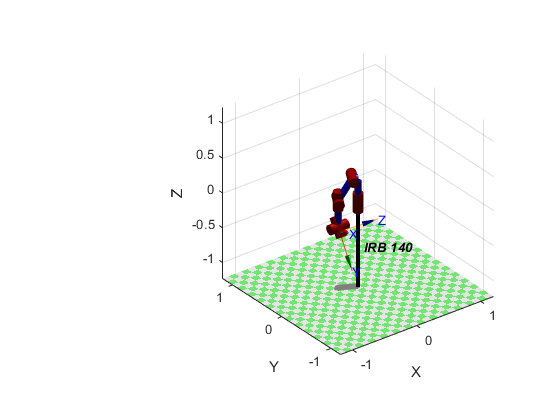

q_st = [pi/4 pi/4 pi/10 pi/10 pi/15 pi/5];
q_end = deg2rad([150 60 120 60 30 20]);
irb140.plot(q_end)

Теперь с помощью функции jtraj рассчитаем траекторию, задав количество шагов

n = 100;
[q, q_d, q_dd] = jtraj(q_st,q_end,n);

Решим обратную задачу динамики

Qp = irb140.rne(q,q_d,q_dd); % получили силы и моменты на каждом звене, необходимые для перемещения по траектории
Qp0 = irb140.rne(q,zeros(100,6),zeros(100,6)); % силы для удержания манипулятора на весу без движения (компенсация гравитации)

Выведем компоненты уравнения динамики для каждого шага

Gp = irb140.gravload(q); % вектор гравитационных сил, совпадает с Qp0
Mp = irb140.inertia(q); % матрица масс
Cp = irb140.coriolis(q, q_d); % вектор кориолисовых и центробежных сил С

Построим необходимые графики моментов для каждого звена в случае движения по траектории и компенсации гравитации

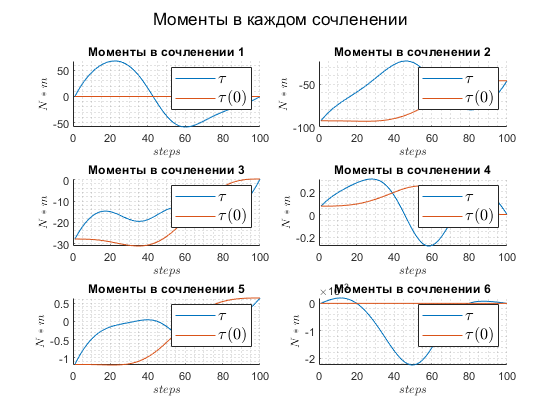

figure;
sgtitle('Моменты в каждом сочленении') 
for i = 1:6
    subplot(3,2,i);
    hold on;
    plot(Qp(:,i))
    plot(Qp0(:,i))
    title(['Моменты в сочленении ', num2str(i)])
    ylabel('$N * m$','interpreter','latex');
    xlabel('$steps$','interpreter','latex');
    grid minor;
    legend('$\tau$', '$\tau(0)$', 'fontsize',12,'interpreter','latex');
end

На графиках представлены моменты в каждом сочленении для случая движения по траектории и для удержания звена в определённом положении в случае отсутствия движения. Видно, что в начальный и конечный моменты времени значения графиков совпадают, поскольку в эти моменты ускорение и скорости равны 0.

Теперь построим графики для каждого элемента уравнения динамики. Также рассчитаем моменты для каждого шага

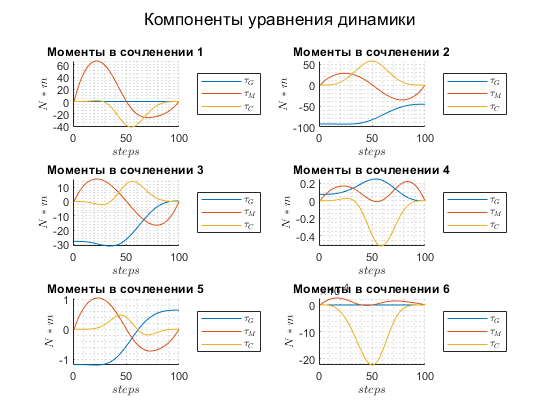

tM = zeros(n, 6);
tc = zeros(n, 6);
for i = 1 : n
    tM(i,:) = Mp(:,:,i) * q_dd(i,:)'; % берём матрицу инерции 6 х 6 для каждого шага
    % и умножаем её на транспонированное ускорение (6 х 1), получаем момент
    tc(i,:) = Cp(:,:,i) * q_d(i,:)'; % матрицу кор. и центр. сил на трансп. скорость
end
figure
sgtitle('Компоненты уравнения динамики') 
for i=1:6
    subplot(3,2,i)
    hold on
    plot(Gp(:,i))
    plot(tM(:,i))
    plot(tc(:,i))
    title(['Моменты в сочленении ' , num2str(i)])
    ylabel('$N * m$','interpreter','latex');
    xlabel('$steps$','interpreter','latex');
    grid minor;
    legend('$\tau_G$', '$\tau_M$','$\tau_C$','interpreter','latex','location', 'eastoutside'); 
end

По графикам можно заключить, что для разных звеньев разные составляющие вносят разный вклад. Например, видно, что для первого звена наибольший вклад вносит матрица инерций, однако для второго звена матрица инерций и матрица центробежных сил вносят примерно равный вклад. При этом, как уже отмечалось ранее, поведение гравитационной составляющей совпадает с общим моментом в случае, когда скорость и ускорения равны 0.

**Вывод:**

В ходе выполнения лабораторной работы был запущена модель робота ABB IRB140 из Robotics Toolbox. Была получена конфигурация робота, определены центры масс звеньев и их тензоры инерции. Была также решена обратная задача динамики, получены графики моментов для каждого звена и графики каждой составляющей уравнения динамики для каждого звена. 